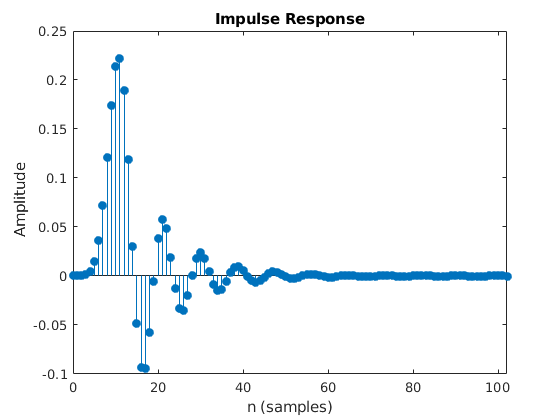

% Task 2
Fs = 40000;
Rp=0.3;
Rs=45;
fs = 7000;
fp = 4000;
fs_n = 2*(fs / Fs);
fp_n = 2*(fp/ Fs);
[N, Wn] = buttord (fp_n, fs_n, Rp, Rs);
[a,b] = butter(N,Wn);
impz(a,b);

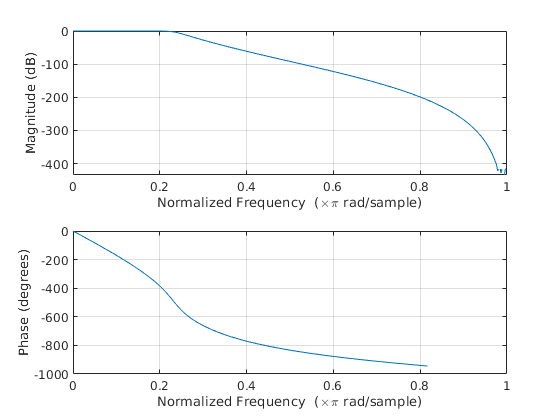

freqz(a,b);

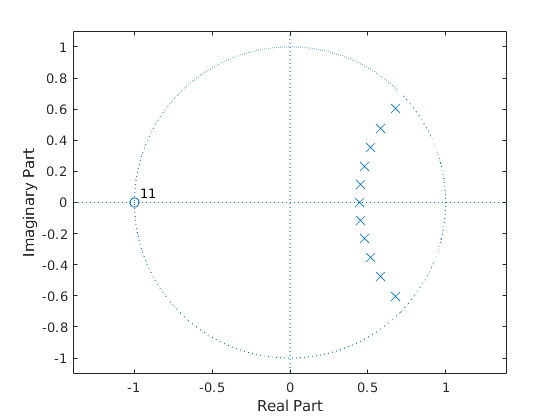

[z,p,K] = butter(N,Wn);
zplane(z,p);

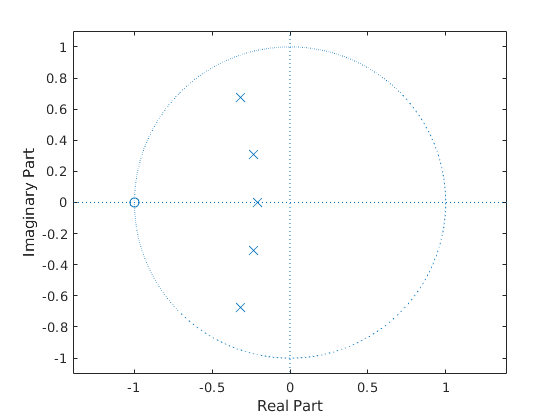

% Task 5
fp=9;
fs=12.5;
Rp=0.4;
Rs=25;
Fs=32;

[N,D] = design_lowpass(fp, fs, Rp, Rs, Fs);

zplane(N,D);

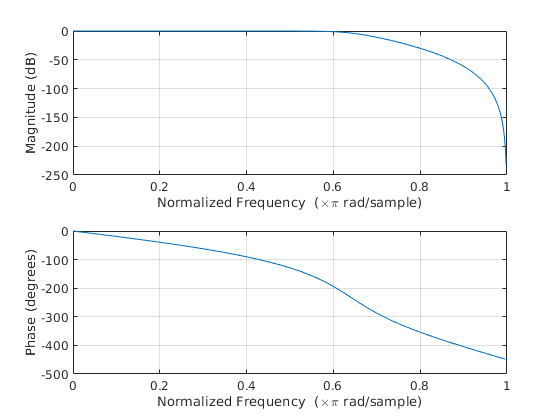

freqz(N,D);

function [N,D] = design_lowpass(fp, fs, Rp, Rs, Fs)
i = sqrt(-1); 
omega_p = 2*pi*fp/Fs; 
omega_s = 2*pi*fs/Fs; 
c = 1/tan(omega_p/2); 
Omega_p = 1; 
Omega_s = c*tan(omega_s/2);
epsilon = sqrt(10^(Rp/10)-1);
A = sqrt(10^(Rs/10)); 
M = ceil(log10((A^2-1)/epsilon^2)/(2*log10(Omega_s))); 
p1 = zeros (1,M); 
for k=1:M 
    p1(k)=(1/epsilon^(1/M))*exp(pi*i*(1/2+(2*k-1)/(2*M)));
end 
p2 = (1+p1/c)./(1-p1/c); 
z = -ones(1,M);
[N,D] = zp2tf(z',p2',1);
K = sum(N)/sum(D); 
N = N/K; 
end 